% State Space Modelling for a Rocket
% Felix Zauner
% 22.02.2026
x0 = zeros(9,1);
x0(1) = 20; % u initial speed
x0(7) = 0;
x0(8) = 0;

u_in = [0; 0; 0; 20]; % delta_eta, delta_zeta, delta_r, T

% Nonlinear Function for a Rocket
function xdot = rocket_f(~, x, u_in)
% x = [u v w p q r phi theta psi]'
% u_in = [delta_eta delta_zeta delta_r T]' 

% Define Parameters
% --- Geometry / environment ---
g0   = 9.81;        % m/s^2
rho0 = 1.225;       % kg/m^3 (sea level)
S    = 0.010;       % m^2  reference area
d    = 0.10;        % m    reference diameter

% --- Mass / inertia ---
m  = 1.20;          % kg
Ix = 0.005;         % kg*m^2
Iy = 0.020;         % kg*m^2 
Iz = 0.020;         % kg*m^2

% --- Aerodynamic force coeffs ---
CA0       = 0.09;   % axial (drag-like)
CA_kalpha = 0.041;   % axial vs alpha
CA_kbeta  = 0.041;   % axial vs beta


% --- Moment coeffs ---
Cl_delta = 0.229;    % roll control effectiveness
Clp      = -10;     % roll damping
Cm_alpha = 2.0;    % pitch stability derivative
Cm_delta = 1.432;    % pitch control effectiveness
Cmq      = -10;     % pitch damping
Cn_beta  = 2.0;     % yaw stability derivative
Cn_delta = 1.432;     % yaw control effectiveness
Cnr      = -10;     % yaw damping

CY_beta = -10;
CY_zeta = -1;

CZ_alpha = -10;
CZ_eta = -1;

% --- Reference points ---
xcm  = 0.50;        % m 
xref = 0.45;        % m 

% --- unpack state ---
ub    = x(1);  vb = x(2);  wb = x(3);       
p     = x(4);  q  = x(5);  r  = x(6);
phi   = x(7);  theta = x(8); psi = x(9);

% --- unpack inputs ---
delta_eta  = u_in(1);
delta_zeta = u_in(2);
delta_r    = u_in(3);
T          = u_in(4);

% --- derived quantities ---
V = sqrt(ub^2 + vb^2 + wb^2) + 1e-9;  % avoid div0
alpha = tan(wb/ub);
beta  = tan(vb/ub);  

% Dynamic pressure q = 1/2 p V^2 for moments
Qdyn = 0.5*rho0*V^2;


CA = CA0 + CA_kalpha*alpha + CA_kbeta*beta;

% Build direct force coefficiants
CY = CY_beta*beta + CY_zeta*delta_zeta;
CZ = CZ_alpha*alpha + CZ_eta*delta_eta;

% Aerodynamic forces 
FAxb = -Qdyn * CA  * S;
FAyb =  Qdyn * CY * S;
FAzb =  Qdyn * CZ * S;

% --- thrust in body ---
FPxb = T;  FPyb = 0;  FPzb = 0;

% --- gravity in body: Fg_b = R_nb' * [0;0;mg] in NED ---
Fg_b = gravity_body(phi, theta, psi, m, g0); 
Fgxb = Fg_b(1); Fgyb = Fg_b(2); Fgzb = Fg_b(3);

% --- total forces ---
Fx = FAxb + FPxb + Fgxb;
Fy = FAyb + FPyb + Fgyb;
Fz = FAzb + FPzb + Fgzb;

% --- moment coefficients  ---
Cl = Cl_delta*delta_r + (d/(2*V))*Clp*p;

% Pitch & yaw moment coefficients
Cmref = Cm_alpha*alpha + Cm_delta*delta_eta;
Cnref = Cn_beta *beta  + Cn_delta*delta_zeta;

Cm = Cmref - CZ*((xcm-xref)/d) + (d/(2*V))*(Cmq + Cm_alpha)*q;
Cn = Cnref - CY*((xcm-xref)/d) + (d/(2*V))*(Cnr + Cn_beta )*r;

LA = Qdyn * Cl * S * d;
MA = Qdyn * Cm * S * d;
NA = Qdyn * Cn * S * d;

% Propulsion moments 
Lp = 0; Mp = 0; Np = 0;

% --- translational dynamics in body ---
udot = Fx/m - (q*wb - r*vb);
vdot = Fy/m - (r*ub - p*wb);
wdot = Fz/m - (p*vb - q*ub);

% --- rotational dynamics ---
pdot = (LA + Lp - q*r*(Iz - Iy))/Ix;
qdot = (MA + Mp - r*p*(Ix - Iz))/Iy;
rdot = (NA + Np - p*q*(Iy - Ix))/Iz;

% --- Euler kinematics ---
phidot   = p + (q*sin(phi) + r*cos(phi))*tan(theta);
thetadot = q*cos(phi) - r*sin(phi);
psidot   = (q*sin(phi) + r*cos(phi))/cos(theta);

xdot = [udot; vdot; wdot; pdot; qdot; rdot; phidot; thetadot; psidot];
end

% Gravity
function Fg_b = gravity_body(phi, theta, psi, m, g)
% NED: gravity in nav frame is [0;0; +m*g] (Down positive)
Fg_n = [-m*g; 0;0];

% Rotation matrix R_b^n (ZYX) and R_n^b = (R_b^n)'
R_b_n = eul2Rbn(phi, theta, psi);  % body->nav
R_n_b = R_b_n';

Fg_b = R_n_b * Fg_n;
end

function R_b_n = eul2Rbn(phi, theta, psi)
cphi = cos(phi); sphi = sin(phi);
cth  = cos(theta); sth = sin(theta);
cps  = cos(psi); sps  = sin(psi);

% ZYX: body->nav (matches common aerospace convention)
R_b_n = [ cth*cps,  sphi*sth*cps - cphi*sps,  cphi*sth*cps + sphi*sps;
          cth*sps,  sphi*sth*sps + cphi*cps,  cphi*sth*sps - sphi*cps;
          -sth,     sphi*cth,              cphi*cth ];
end

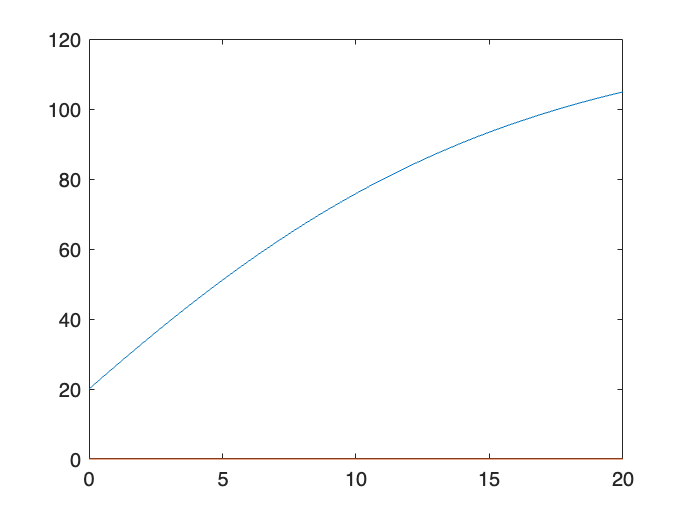

tspan = [0 20];
[t,x] = ode45(@(t,x) rocket_f(t,x,u_in), tspan, x0);
plot(t,x)